# パラメータを更新

clear
clf

%重力加速度
g = 9.8; %[m/s^2]


% 機構的なパラメータ
M = 2000e-3; % 重量[kg]
l1 = 100e-3; % 第1リンクの長さ[m]
l2 = 100e-3; % 第2リンクの長さ[m]

% モータのパラメータ
V_input = 48; % 印加電圧[V]
V_nominal = 24; %モータの公称電圧[V]
voltage_constant_times = V_input / V_nominal;

n_max = 4530 * voltage_constant_times; % 無負荷回転数[rpm]
omega_max = (n_max * 2 * pi) / 60; % 無負荷角速度[rad/s]
T_max = 85.3e-3 * voltage_constant_times; % 停動トルク[Nm]

n_const = 195 * voltage_constant_times; % 回転数定数[rpm/V]
omega_const = n_const * 2 * pi / 60; % 角速度定数[rad/V]
T_const = 49e-3 * voltage_constant_times; %トルク定数[Nm/A]


# モータの特性をプロット

#### 回転数-トルク特性

% sloop = -n_max / T_max; %傾きを計算
% fplot(@(x) sloop * x + n_max, [0 T_max]);
torque_motor = linspace(0, T_max);
n_motor = linspace(n_max, 0);
plot(torque_motor, n_motor);
xlabel("トルク [Nm]")
ylabel("回転数 [rpm]")

#### 出力特性

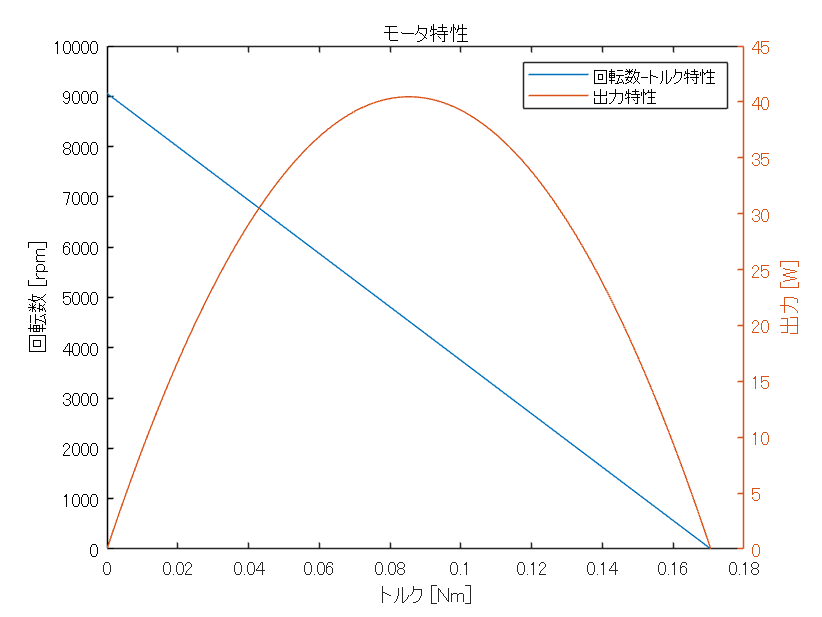

omega_motor = linspace(omega_max, 0);
P_motor = torque_motor .* omega_motor; %出力を計算

hold on
yyaxis right
plot(torque_motor, P_motor);
ylabel("出力 [W]")
legend("回転数-トルク特性", "出力特性")
title("モータ特性")

cla reset
hold off

P_motor = max(double(P_motor)) %モータの最大出力

P_motor = 40.4605

p_motor = (omega_max / 2) * (T_max / 2) % 厳密解

p_motor = 40.4647

# 自重を支えることができるトルクを計算

関節を伸ばしきって，根本の関節で持ち上げるときのトルク

theta1 = deg2rad(180); %関節の角度
phi1 = pi - theta1;

F_M = -(1/4) * M * g;
T1 = (l1 + l2) * F_M * cos(phi1)

T1 = -0.9800

# 脚に必要な出力を算出

任意の高さをジャンプできる出力を計算

% 各関節にに必要な角速度とトルク．
% シミュレーションで確認した値
omega_joint_need = 70;
torque_joint_need = 0.35; 

% タイヤに必要な出力（効率考慮済み）
P_joint_need = omega_joint_need * torque_joint_need

P_joint_need = 24.5000

# 減速機なしの状態で駆動点と比較

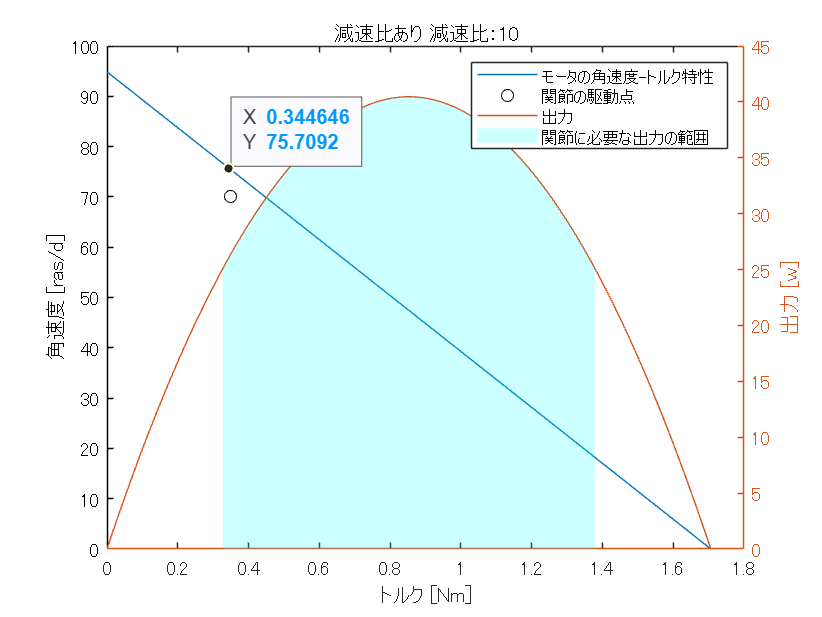

 % 角速度-トルク特性
plot(torque_motor, omega_motor);

hold on
% 出力
P_n = torque_motor .* omega_motor; %出力を計算
yyaxis right
plot(torque_motor, P_n); % 出力特性
ylabel("出力 [w]")

% 必要な出力の範囲
above_idx = find(P_n >= P_joint_need); %P_tire_need以上の出力のインデックスを取得
area(torque_motor(above_idx), P_n(above_idx), 'LineStyle', 'none', 'FaceColor', 'cyan', 'FaceAlpha', 0.2) %塗りつぶし
yyaxis left

% 駆動点
scatter(torque_joint_need, omega_joint_need);

hold off

xlabel("トルク [Nm]")
ylabel("角速度 [ras/d]")
legend("モータの角速度-トルク特性", "関節の駆動点", "出力", "関節に必要な出力の範囲")
title("減速機なし")


cla reset

# 減速比によって特性グラフと駆動点がどのように移動するか確認

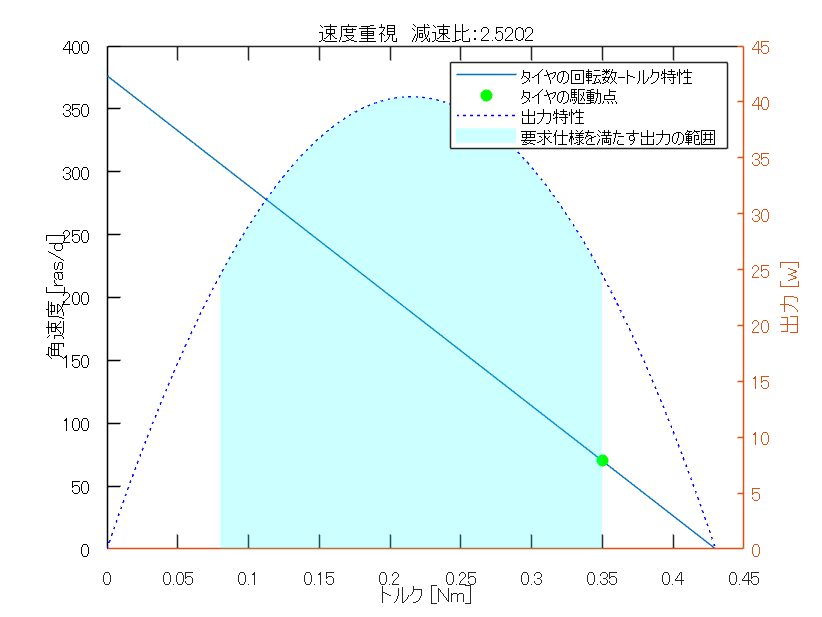

ratio_guess = 10; %適当な減速比を入力．大きくなると角速度：小，トルク：大
plot(torque_motor * ratio_guess, omega_motor / ratio_guess); % 角速度-トルク特性
hold on

% 出力
P_n = (torque_motor * ratio_guess) .* (omega_motor / ratio_guess); %出力を計算
yyaxis right
plot((torque_motor * ratio_guess), P_n); % 出力特性
ylabel("出力 [w]")

% 必要な出力の範囲
above_idx = find(P_n >= P_joint_need); %P_tire_need以上の出力のインデックスを取得
area((torque_motor(above_idx) * ratio_guess), P_n(above_idx), 'LineStyle', 'none', 'FaceColor', 'cyan', 'FaceAlpha', 0.2) %塗りつぶし

yyaxis left

scatter(torque_joint_need, omega_joint_need);

hold off

xlabel("トルク [Nm]")
ylabel("角速度 [ras/d]")
legend("モータの角速度-トルク特性", "関節の駆動点", "出力", "関節に必要な出力の範囲")
title(['減速比あり 減速比：', num2str(ratio_guess)])


cla reset


# 条件を満たす範囲のイメージ

青い線がオレンジの線より上にあれば要求を満たす．

syms omega_m gamma T_m T_n omega_n tau %omega(tau) omega_a(tau)

omega = -(omega_m / T_m) * gamma^2 * tau + omega_m * gamma

$$omega = \gamma \,\omega_{m}-\frac{\gamma^{2}\,\omega_{m}\,\tau }{T_{m}}$$

omega_a = -(omega_m / T_m) * gamma^2 * (tau - T_n) + omega_n

$$omega\_a = \omega_{n}+\frac{\gamma^{2}\,\omega_{m}\,\left(T_{n}-\tau \right)}{T_{m}}$$


%代入
ratio_guess = 1/2; %適当な減速比を入力．

omega = subs(omega, [gamma T_n omega_n T_m omega_m], [ratio_guess torque_joint_need omega_joint_need T_max omega_max])

$$omega = 151\,\pi -\frac{377500\,\pi \,\tau }{853}$$

omega_a = subs(omega_a, [gamma T_n omega_n T_m omega_m], [ratio_guess torque_joint_need omega_joint_need T_max omega_max])

$$omega\_a = 70-\frac{377500\,\pi \,\left(\tau -\frac{7}{20}\right)}{853}$$

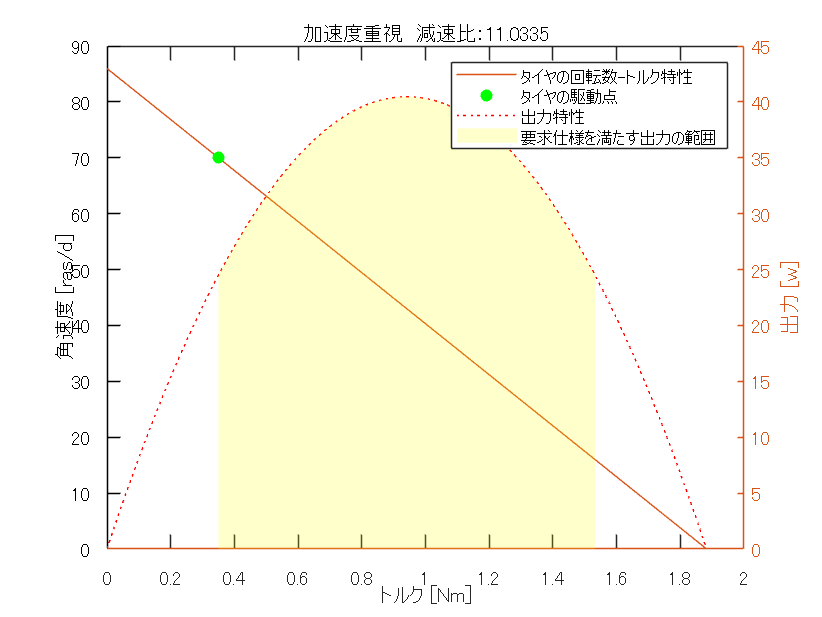


%減速比を介したタイヤの特性グラフ
fplot(omega, [0 torque_joint_need*2])

hold on

%減速比（傾き）が同じで駆動点を通る線（要求を満たす限界ライン）
fplot(omega_a, [0 torque_joint_need*2])

ylim([0 omega_joint_need*2])

scatter(torque_joint_need, omega_joint_need, 'red', 'filled')
hold off

xlabel("トルク [Nm]")
ylabel("角速度 [ras/d]")
legend("\omega：減速比を介した特性", "\omega_a：同じ減速比で駆動点を通る線", "駆動点")
title(['減速比あり 減速比：', num2str(ratio_guess)])

# 条件を満たす減速比の範囲を計算（1）

減速比なしのモータの出力から計算．wikiに書いてある方法．式の途中で減速比をいきなり考慮しちゃっている以外はwikiと同じだと思われ．

syms P_n
eqn1 = -(omega_m / T_m) * tau^2 + omega_m * tau == P_n % 出力の2次方程式の解がPnになる式

$$eqn1 = \omega_{m}\,\tau -\frac{\omega_{m}\,\tau^{2}}{T_{m}}=P_{n}$$


eqn1 = subs(eqn1, tau, T_n * gamma) %gammaについての式に変換

$$eqn1 = T_{n}\,\gamma \,\omega_{m}-\frac{{T_{n}}^{2}\,\gamma^{2}\,\omega_{m}}{T_{m}}=P_{n}$$


eqn1 = solve(eqn1, gamma) % gammaについて解く

$$eqn1 = \left(\begin{array}{c} \frac{T_{m}\,\left(\omega_{m}+\sqrt{-\frac{\omega_{m}\,\left(4\,P_{n}-T_{m}\,\omega_{m}\right)}{T_{m}}}\right)}{2\,T_{n}\,\omega_{m}}\\ \frac{T_{m}\,\left(\omega_{m}-\sqrt{-\frac{\omega_{m}\,\left(4\,P_{n}-T_{m}\,\omega_{m}\right)}{T_{m}}}\right)}{2\,T_{n}\,\omega_{m}} \end{array}\right)$$


eqn1_num = subs(eqn1, [omega_m T_m T_n omega_n P_n], [omega_max T_max torque_joint_need omega_joint_need P_joint_need]) %値を代入

$$eqn1\_num = \left(\begin{array}{c} \frac{853\,\left(302\,\pi +\sqrt{\frac{1510000\,\pi \,\left(\frac{128803\,\pi }{2500}-98\right)}{853}}\right)}{1057000\,\pi }\\ \frac{853\,\left(302\,\pi -\sqrt{\frac{1510000\,\pi \,\left(\frac{128803\,\pi }{2500}-98\right)}{853}}\right)}{1057000\,\pi } \end{array}\right)$$


g = double(eqn1_num) % 減速比

g =     0.3968
    0.0906


% 

# 条件を満たす減速比の範囲を計算（2）

駆動点より上にタイヤの角速度-トルク特性がくるような条件から計算．別解．

eqn1 = omega_m * gamma == (omega_m/T_m) * gamma^2 * T_n + omega_n 

$$eqn1 = \gamma \,\omega_{m}=\omega_{n}+\frac{T_{n}\,\gamma^{2}\,\omega_{m}}{T_{m}}$$


eqn1 = solve(eqn1, gamma) %減速比について解く（減速比：γ）

$$eqn1 = \left(\begin{array}{c} \frac{T_{m}\,\left(\omega_{m}+\sqrt{\frac{\omega_{m}\,\left(T_{m}\,\omega_{m}-4\,T_{n}\,\omega_{n}\right)}{T_{m}}}\right)}{2\,T_{n}\,\omega_{m}}\\ \frac{T_{m}\,\left(\omega_{m}-\sqrt{\frac{\omega_{m}\,\left(T_{m}\,\omega_{m}-4\,T_{n}\,\omega_{n}\right)}{T_{m}}}\right)}{2\,T_{n}\,\omega_{m}} \end{array}\right)$$


eqn1_num = subs(eqn1, [omega_m T_m T_n omega_n], [omega_max T_max torque_joint_need omega_joint_need]) % 値を代入

$$eqn1\_num = \left(\begin{array}{c} \frac{853\,\left(302\,\pi +\sqrt{\frac{1510000\,\pi \,\left(\frac{128803\,\pi }{2500}-98\right)}{853}}\right)}{1057000\,\pi }\\ \frac{853\,\left(302\,\pi -\sqrt{\frac{1510000\,\pi \,\left(\frac{128803\,\pi }{2500}-98\right)}{853}}\right)}{1057000\,\pi } \end{array}\right)$$


g = double(eqn1_num) % 減速比

g =     0.3968
    0.0906


# プロットしてみる

#### 減速比が低いとき（速度重視）

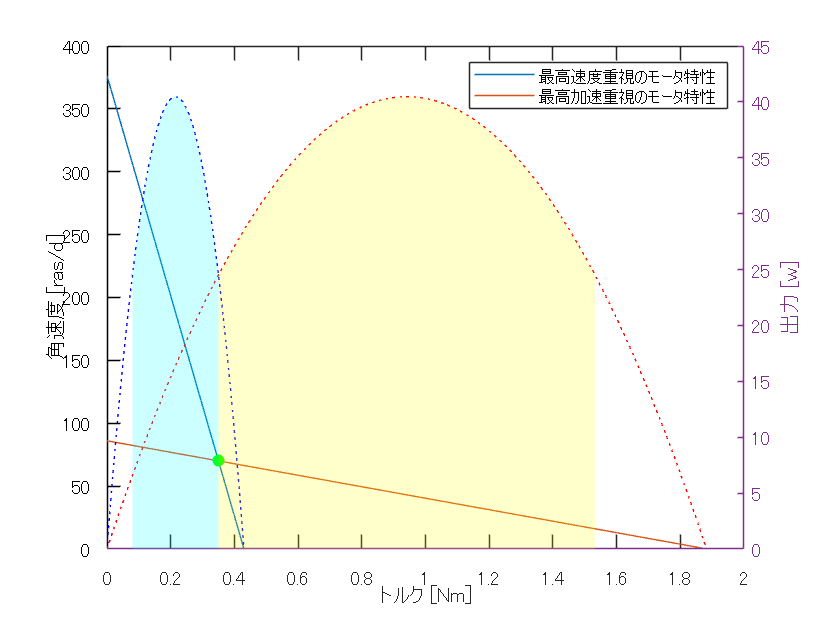

%減速比をかけた角速度-トルク曲線をプロット
ratio_min = g(1);
torque_motor_ratio_min = linspace(0, T_max * (1/ratio_min), 2000);
omega_motor_ratio_min= linspace(omega_max * ratio_min, 0, 2000);

plot(torque_motor_ratio_min, omega_motor_ratio_min, 'Color', [0 0.4470 0.7410]); % 角速度-トルク特性
xlabel("トルク [Nm]")
ylabel("角速度 [ras/d]")

% 出力をプロット
P_ratio_num_min = torque_motor_ratio_min .* omega_motor_ratio_min; %出力を計算
yyaxis right
hold on
plot(torque_motor_ratio_min, P_ratio_num_min, 'LineStyle', ':', 'Color', 'blue'); % 出力特性
ylabel("出力 [w]")

% 要求仕様を満たす出力の範囲
above_idx_min = find(P_ratio_num_min >= P_joint_need); %P_tire_need以上の出力のインデックスを取得
area(torque_motor_ratio_min(above_idx_min), P_ratio_num_min(above_idx_min), 'LineStyle', 'none', 'FaceColor', 'cyan', 'FaceAlpha', 0.2)


% 加減速時の駆動点をプロット
yyaxis left
scatter(torque_joint_need, omega_joint_need, "green", 'filled'); %駆動点
hold off

legend("タイヤの回転数-トルク特性", "タイヤの駆動点", "出力特性", "要求仕様を満たす出力の範囲")
title(['速度重視　減速比：', num2str(1/g(1))])


cla reset

#### 減速比が高いとき（加速重視）

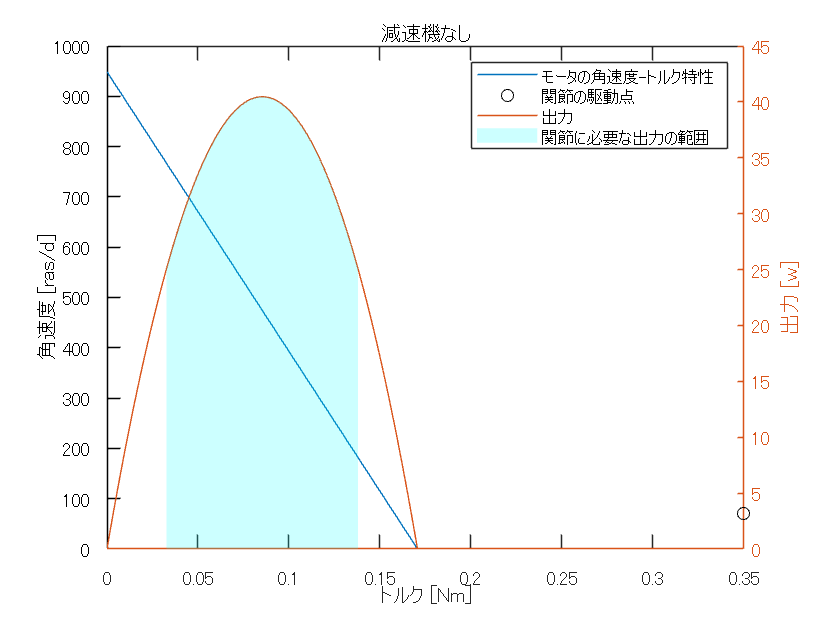

%減速比をかけた角速度-トルク曲線をプロット

ratio_max = g(2);
torque_motor_ratio_max = linspace(0, T_max * (1/ratio_max), 2000);
omega_motor_ratio_max = linspace(omega_max * ratio_max, 0, 2000);

plot(torque_motor_ratio_max, omega_motor_ratio_max, 'Color', [0.8500 0.3250 0.0980]); % 角速度-トルク特性
xlabel("トルク [Nm]")
ylabel("角速度 [ras/d]")

% 出力をプロット
P_ratio_num_max = torque_motor_ratio_max .* omega_motor_ratio_max; %出力を計算
yyaxis right
hold on
plot(torque_motor_ratio_max, P_ratio_num_max, 'LineStyle', ':', 'Color', 'red'); % 出力特性
ylabel("出力 [w]")

% 要求仕様を満たす出力の範囲
above_idx_max = find(P_ratio_num_max >= P_joint_need); %P_tire_need以上の出力のインデックスを取得
area(torque_motor_ratio_max(above_idx_max), P_ratio_num_max(above_idx_max), 'LineStyle', 'none', 'FaceColor', 'yellow', 'FaceAlpha', 0.2)


% 加減速時の駆動点をプロット
yyaxis left
scatter(torque_joint_need, omega_joint_need, "green", 'filled'); %駆動点
hold off

legend("タイヤの回転数-トルク特性", "タイヤの駆動点", "出力特性", "要求仕様を満たす出力の範囲")
title(['加速度重視　減速比：', num2str(1/g(2))])


cla reset

#### 重ねて表示

%モータ特性をプロット
plot(torque_motor_ratio_min, omega_motor_ratio_min, torque_motor_ratio_max, omega_motor_ratio_max); % 角速度-トルク特性
xlabel("トルク [Nm]")
ylabel("角速度 [ras/d]")

hold on
% 加減速時の駆動点をプロット
scatter(torque_joint_need, omega_joint_need, "green", 'filled'); %駆動点

%　出力をプロット
yyaxis right
plot(torque_motor_ratio_min, P_ratio_num_min, 'LineStyle', ':', 'Color', 'blue'); % 出力特性
plot(torque_motor_ratio_max, P_ratio_num_max, 'LineStyle', ':', 'Color', 'red'); % 出力特性

ylabel("出力 [w]")

area(torque_motor_ratio_min(above_idx_min), P_ratio_num_min(above_idx_min), 'LineStyle', 'none', 'EdgeColor', 'black', 'FaceColor', 'cyan', 'FaceAlpha', 0.2)
area(torque_motor_ratio_max(above_idx_max), P_ratio_num_min(above_idx_max), 'LineStyle', 'none', 'EdgeColor', 'black', 'FaceColor', 'yellow', 'FaceAlpha', 0.2)

hold off

legend("最高速度重視のモータ特性", "最高加速重視のモータ特性")